# **Tutorial 3:** robust attitude control design of a spacecraft with 2 symmetrical rotating solar arrays ( $\approx 4\,mn$ run).

*by D. Alazard and F. Sanfedino - ISAE-SUPAERO*

## 1. Description

The objective is to design the Attitude Control System of the spacecraft  presented in the tutorial 2: [***a spacecraft with 2 symmetrical rotating solar arrays***](matlab:open('../Tutorial2/tutorial2.html'))***.***

The SIMULINK model is thus the same except that $20\%$ of relative uncertainty is taken into account on the :

- the mass of the main body $\mathcal B$: `mB,`

- the $3$ terms on the diagonal of the main body inertia: $\mathbf J^{\mathcal B}_B$: `IBx, IBy, IBz,`

- the frequency of the 3 flexible modes of the solar array (identical for the 2 solar arrays): `w1, w2, w3`.

SCwith2SAs2aug
Gu=ulinearize('SCwith2SAs2aug')

Gu =

  Uncertain continuous-time state-space model with 18 outputs, 8 inputs, 28 states.
  The model uncertainty consists of the following blocks:
    IBx: Uncertain real, nominal = 75, variability = [-20,20]%, 1 occurrences
    IBy: Uncertain real, nominal = 40, variability = [-20,20]%, 1 occurrences
    IBz: Uncertain real, nominal = 80, variability = [-20,20]%, 1 occurrences
    mB: Uncertain real, nominal = 1e+03, variability = [-20,20]%, 3 occurrences
    tan_Theta_div4: Uncertain real, nominal = 0, range = [-1,1], 32 occurrences
    w1: Uncertain real, nominal = 5.6, variability = [-20,20]%, 4 occurrences
    w2: Uncertain real, nominal = 19.3, variability = [-20,20]%, 4 occurrences
    w3: Uncertain real, nominal = 35.4, variability = [-20,20]%, 4 occurrences

Type "Gu.NominalValue" to see the nominal value, "get(Gu)" to see all properties, and "Gu.Uncertainty" to interact with the uncertain elements.



This tutorial aims to show that the SIMULINK models made with `SDTlib` are compatible with the robust control toolbox. The numerical data are given as an example and are not necesseraly representative of a real application.

We consider the robust design of a $3$- axis  structured attitude control law to meet:

- (`Req1`) the pointing requirement (defined by the $3\times 1$ vector `APE`) in spite of low frequency orbital disturbances (characterized by the $3\times 1$ upper bound on the magnitude `Tpert`),

- (`Req2``)` stability margins characterized by an upper bound $\gamma$ (`gamma`) on the $H_\infty$ norm of the input sensitivity function.

while minimizing (`Req3`) the variance on the torque applied by the reaction wheel system on the spacecraft in response to the star sensor and gyrometer noises charcacterized by their PSD (Power Spectral Density `PSD_SST` and `PSD_GYRO` (assumed to be equal for the $3$ components).

**Numerical application:**

% APE (Absolute Pointing Error) requirement
APE=[20 10 50]'*0.001*pi/180; % (rad)

% Orital  disturbance magnitude:
Tpert=[0.02 0.01 0.02]'; %( Nm)

% PSD of sensor noises:
PSD_GYRO=1e-10;  %(rd^2/s), 
PSD_SST=1e-8;    % (rd^2.s),

% Upper bound on the input sensitivity function
gamma=1.5;

The value $\gamma=1.5$ ensures on each of the 3 axes:

- a modulus margin $>1/\gamma=0.666$,

- a gain margin $>\frac{\gamma}{\gamma-1}=3\;(9.54\;dB)$,

- a phase margin $>2\arcsin\frac{1}{2\gamma}=38.9\,(deg)$.

The requirements `Req1` and `Req2` must be met for any values of:

- the mechanical parameter $\mathbf \Delta$ (composed of the $7$ parameters: `mB, IPx, IBy, IBz w1, w2, w3`),

- the geometrical configuration $\theta$ of the solar arrays.

The performance index `Req3` is measured on the worst-case parametric configuration in $\mathbf \Delta$, $\theta$.

## 2. The design model

The design model is the SIMULINK file `SC_CL_model.slx` depicted in the following Figure.

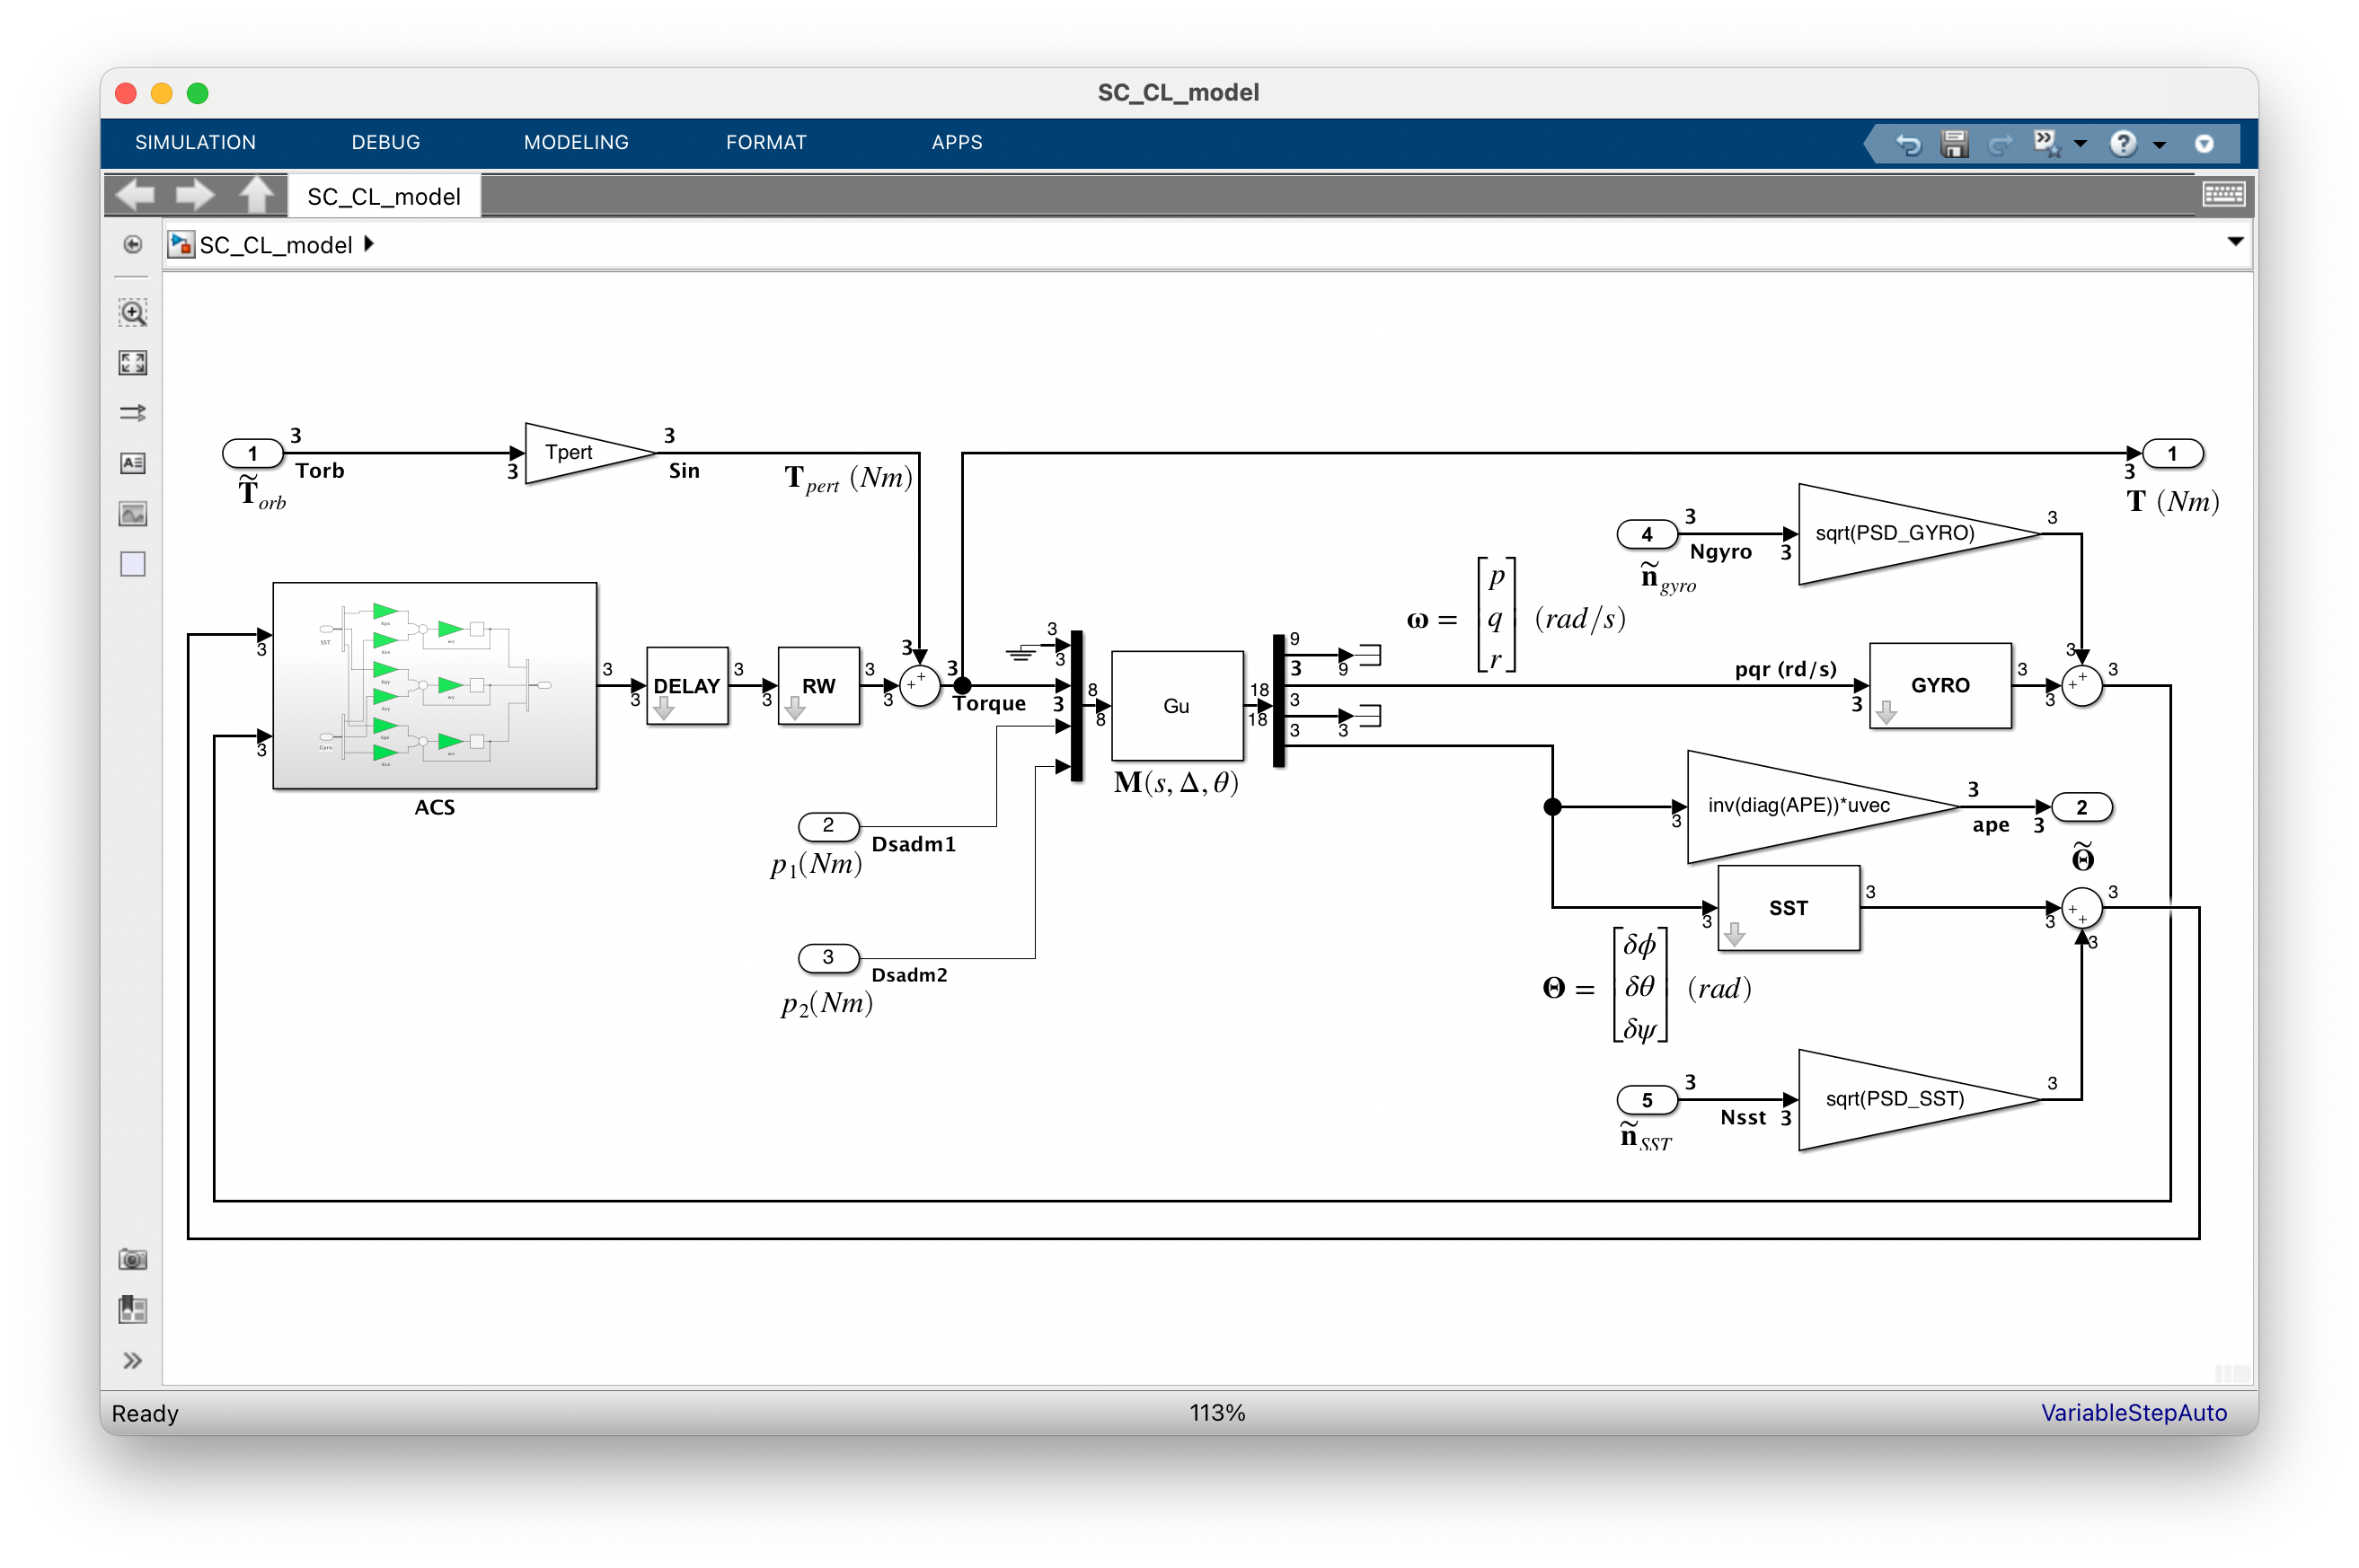

The model previously computed $\mathbf M(\mathrm s,\mathbf\Delta,\theta)$ (`Gu`) is introduced with an `Uncertain State Space `from the` Robust Control toolbox `sub-library. Since the design will be based on the SIMULINK model and the Matlab/Simulink `slTuner` interface, it is very important to specify again **Gu **in the` Linear Analysis > Specify Selected Block Linearization` menu (obtained by a right click on the block `Gu`) according to he following Figure.

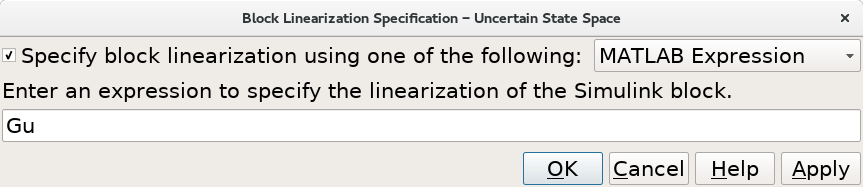

Then the design model is completed with $3\times 3$ avionics models for:

- the reaction wheel system dynamics: `RW`. A second order transfer with a $0.7$ damping ratio and a $100\;Hz$ frequency is assumed on each of the 3 axes,

- the star sensor dynamics: `SST`. A first order transfer with a $8\,Hz$ cut-off frequency is assumed on each of the 3 axes,

- the gyrometer dynamics: `GYRO`. A first order transfer with a $200\,Hz$ cut-off frequency is assumed on each of the 3 axes,

- a loop delay `DELAY`. A $0.01\,s$ delay, modelled by a second order*** Pade*** approximation, is assumed on each of the 3 axes.

% Avionics:
% RWs: 2nd order low pass at 100 Hz
RW=tf((200*pi)^2,[1 1.4*200*pi (200*pi)^2])*eye(3);
% SST: 1st order low pass at 8 hz
SST=tf(8*2*pi,[1 8*2*pi])*eye(3);
% GYRO: 1sr order low pass at 200 Hz
GYRO=tf(400*pi,[1 400*pi])*eye(3);
% Loop delay
delay=0.01; %(s) : delay to discretizaton, etc ...
[num,den]=pade(delay,2);
DELAY=tf(num,den)*eye(3);

The structured $3\times 6$ attitude controller (ACS) is depicted in the next figure.

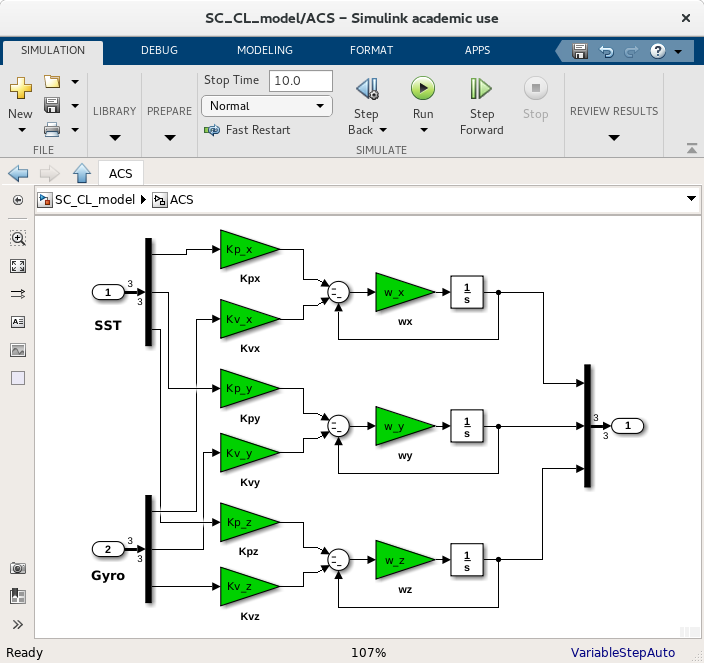

It is a decentralised controller composed of a proportional-derivative controller (the $2$ gains `Kpi`  and `Kvi`,` i=x,y,z`) with a first order low pass filter (characterized by the cut-off frequency` wi`,` i=x,y,z`) per axis. 

The set of the $9$ tunable parameters (`Kpi, wi`  and `Kvi`,` i=x,y,z`) is denoted $\mathbf K$. They are all initialized to $1$.

% Tunable parameter initialization:
Kp_x=1; Kp_y=1; Kp_z=1;
Kv_x=1; Kv_y=1; Kv_z=1;
w_x=1;  w_y=1;  w_z=1;

The inputs and outputs of the closed-loop SIMULINK model `SC_CL_model.slx, `denoted $\mathbf P(\mathrm s,\mathbf\Delta,\theta,\mathbf K)$, are:

- $\tilde\mathbf T_{orb}$ (`Torb`: 3 component input # 1): the normalized (w.r.t. `Tpert`) orbital distrubance (adimensional),

- $p_1$ (`Dsadm1`: 1 component input # 2): the disturbing torque on the SADM # 1 ( $Nm$ ). Not used in the design,

- $p_2$ (`Dsadm2`: 1 component input # 3): the disturbing torque on the SADM # 2 ( $Nm$ ). Not used in the design,

- $\tilde \mathbf n_{gyro}$ (`Ngyro`: 3 component input # 4): the normalized (w.r.t. `PSD_GYRO`) gyro noise ($\sqrt{Hz}$),

- $\tilde \mathbf n_{SST}$ (`Nsst`: 3 component input # 5): the normalized (w.r.t. `PSD_SST`) star sensor noise ($\sqrt{Hz}$),

- $\mathbf T$ (`Torque`: 3 component output # 1): the torque applied on the spacecraft by the reactions wheels ( $Nm$),

- $\tilde\mathbf\Theta$ (**ape**: 3 component output  # 2): the normalized (w.r.t. `APE`) attitude error (adimensional).

$\mathbf P_{\tilde \mathbf T_{orb}\to \tilde\mathbf\Theta}(\mathrm s,\mathbf\Delta,\theta,\mathbf K)$ denotes  the closed-loop transfer from $\tilde\mathbf T_{orb}$ to $\tilde\mathbf\Theta$ for a given parametric uncertainty vector $\mathbf \Delta$, a given geometric configuration $\theta$ and a given tunable parameter vector $\mathbf K$. $\mathbf P_{\tilde\mathbf n\to \mathbf T}(\mathrm s,\mathbf\Delta,\theta,\mathbf K)$ denotes the closed-loop transfer from the 6 component noise $\tilde \mathbf n=[\tilde \mathbf n_{gyro}^T\quad \tilde \mathbf n_{SST}]^T$ to $\mathbf T$.

In addition the SIMULINK model has some labelled internal signals: $\mathbf T_{pert}\;(Nm)$ (`Sin`) is the input disturbance used to define the input sensitivity function $\bar\mathbf S(\mathrm s, \mathbf\Delta,\theta,\mathbf K)=\mathbf P_{\mathbf T_{pert}\to \mathbf T}(\mathrm s,\mathbf\Delta,\theta,\mathbf K)$.

## 3. Design optimization

The design is made using the MATLAB/SIMULINK interface` slTuner` by specifying the names of the tunable blocks and the names of the signals used to express the various requirements:

SC_CL_model
P0=slTuner('SC_CL_model',{'Kpx','Kvx','wx','Kpy','Kvy','wy','Kpz','Kvz','wz'});
addPoint(P0,{'Torb','Sin','Dsadm1','Dsadm2','Ngyro','Nsst','Torque','ape'});

The first requirement or hard contraint `Req1` on the pointing error reads:


$$\max_{\mathbf\Delta,\theta}\|\mathbf P_{\tilde \mathbf T_{orb}\to \tilde\mathbf\Theta}(\mathrm s,\mathbf\Delta,\theta,\widehat{\mathbf K})\|_\infty \le 1$$


and the corrsponding MATLAB syntax is:

% Hard requirement on the closed-loop transfert:
%  The gain from the normalized orbital disturbances to normalized APE:
Req1=TuningGoal.Gain('Torb','ape',1);
Req1.Name='ape/Spec';

The second requirement or hard constraint `Req2` on the input sensitivity function reads:


$$\max_{\mathbf\Delta,\theta}\|\bar\mathbf S(\mathrm s,\mathbf\Delta,\theta,\widehat{\mathbf K})\|_\infty \le \gamma$$


and the corresponding MATLAB syntax is:

% Hard requirement on the input sensitivity function:
Req2=TuningGoal.Gain('Sin','Torque',gamma);
Req2.Name='Input sensitivity';

The preformance index or soft constraint `Req3` is:

$\widehat J=\max_{\mathbf\Delta,\theta}\|\mathbf P_{\tilde \mathbf n\to \mathbf T}(\mathrm s,\mathbf\Delta,\theta,\widehat{\mathbf K})\|_2$ with $\widehat \mathbf K=\arg\min_{\mathbf K}\max_{\mathbf\Delta,\theta}\|\mathbf P_{\tilde \mathbf n\to \mathbf T}(\mathrm s,\mathbf\Delta,\theta,\mathbf K)\|_2$

and the corresponding MATLAB syntax is:

% Soft requirement on the variance from sensor noises to
% the applied torque:
Req3=TuningGoal.Variance({'Ngyro','Nsst'},'Torque',1);
Req3.Name='Actuator Variance';

The optimization is done thanks to the function `systune` with 2 random initializations in addition to the proposed initialization:

% Design optimisation:
opt=systuneOptions;
opt.RandomStart=2;
[Popt,fBest,gBest,Info] = systune(P0,Req3,[Req1,Req2],opt);

Nominal tuning:
Design 1: Soft = 0.00751, Hard = 0.99992
Design 2: Soft = 0.00751, Hard = 0.99975
Design 3: Soft = 0.00751, Hard = 0.99984

Robust tuning of Design 1:
Soft: [0.00751,Inf], Hard: [1,1.03], Iterations = 242
Soft: [0.00756,Inf], Hard: [1,1], Iterations = 151
Soft: [0.00756,0.00756], Hard: [1,1], Iterations = 153
Final: Soft = 0.00756, Hard = 1, Iterations = 546

Robust tuning of Design 3:
Soft: [0.00751,Inf], Hard: [1,1.03], Iterations = 270
Soft: [0.00755,Inf], Hard: [1,1.01], Iterations = 191
Soft: [0.00756,0.00756], Hard: [1,1], Iterations = 162
Final: Soft = 0.00756, Hard = 0.99999, Iterations = 623

Robust tuning of Design 2:
Soft: [0.00751,Inf], Hard: [1,1.03], Iterations = 248
Soft: [0.00756,Inf], Hard: [1,1], Iterations = 172
Soft: [0.00756,0.00756], Hard: [1,1], Iterations = 170
Final: Soft = 0.00756, Hard = 0.99994, Iterations = 590


gBest

gBest =     1.0000    1.0000


When the 2 components of` gBest` are lower than $1$, the requirements `Req1` and `Req2` are met for any parametric unceratinties $\mathbf\Delta$ and any geometric configuration $\theta$.

fBest

fBest = 0.0076

`fBest` gives the worst-case performance index: $\widehat J=\mathrm{fBest}\;Nm/\sqrt{Hz}$

Then one can get the optimal tuning of the $9$ controller gains $\widehat\mathbf K$:

% Optimal tuning:
w_x=getBlockValue(Popt,'wx');w_x=w_x.d;
w_y=getBlockValue(Popt,'wy');w_y=w_y.d;
w_z=getBlockValue(Popt,'wz');w_z=w_z.d;
Kp_x=getBlockValue(Popt,'Kpx');Kp_x=Kp_x.d;
Kp_y=getBlockValue(Popt,'Kpy');Kp_y=Kp_y.d;
Kp_z=getBlockValue(Popt,'Kpz');Kp_z=Kp_z.d;
Kv_x=getBlockValue(Popt,'Kvx');Kv_x=Kv_x.d;
Kv_y=getBlockValue(Popt,'Kvy');Kv_y=Kv_y.d;
Kv_z=getBlockValue(Popt,'Kvz');Kv_z=Kv_z.d;

## 4. Optimal design analysis

It is now possible to analyse the frequency-domain responses of $2$ constrained transfers (`Req1` and `Req2`) from random samples in the parametric space $\{\mathbf \Delta,\;\theta\}$ and the worst-case identified during the optimization process (`systune`):

% Optimal design analysis:
PB1=getIOTransfer(Popt,'Torb','ape');
PB2=getIOTransfer(Popt,'Sin','Torque');

% Worst-cases identified by systune
% Best run:
[g,index]=min([Info.g])

g = 0.9999

index = 2

% Worst cases identified during the best run:
WCs=Info(index).wcPert;

The first worst-case :

WCs(1)

ans = struct with fields:
               IBx: 60.0000
               IBy: 32
               IBz: 64
                mB: 800
    tan_Theta_div4: -0.8125
                w1: 6.7200
                w2: 23.1600
                w3: 42.4800


The frequency domain response relative to `Req1`:

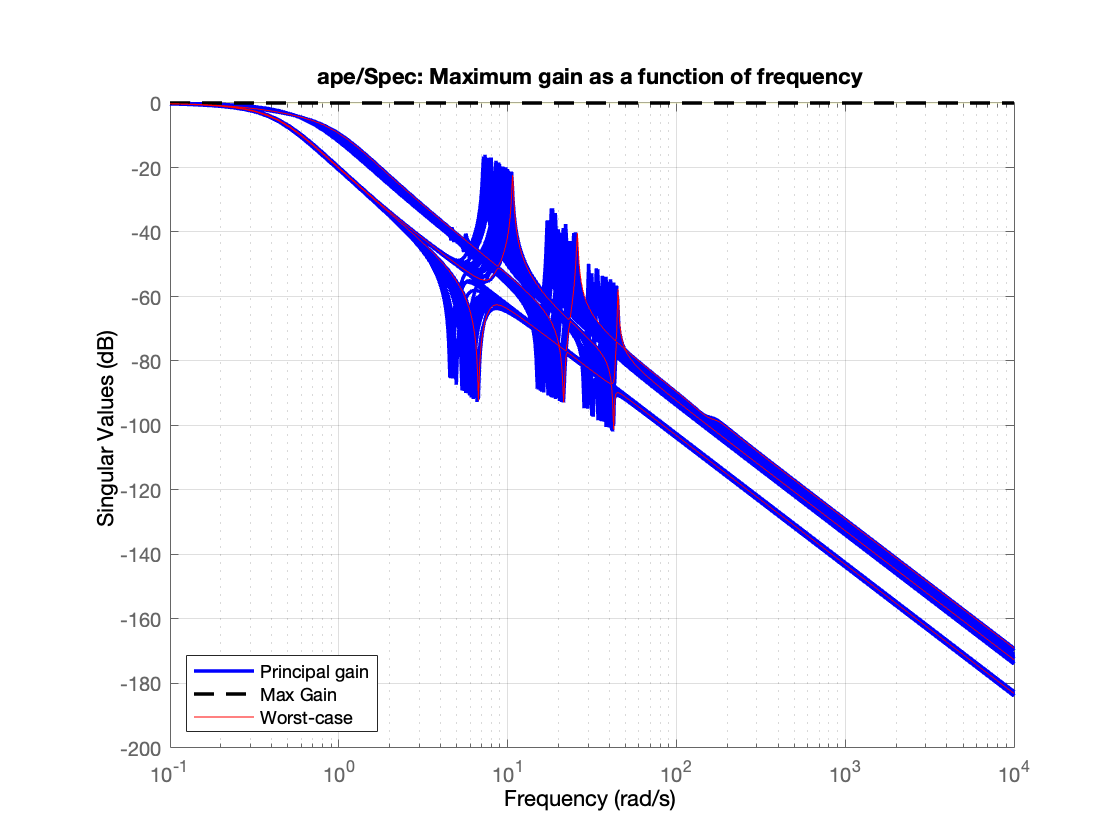

% Frequency domain constraints Req1:
figure
viewGoal(Req1,PB1)
hold on
sigma(usubs(PB1,WCs(1)),'-r')  % worst performance
legend('Principal gain','Max Gain','Worst-case','Location','southwest')

One can check that the hard constraint `Req1` is saturated at the null frequency for any values of the parametric vector and the geometric configuration.

The frequency domain response realtive to `Req2`:

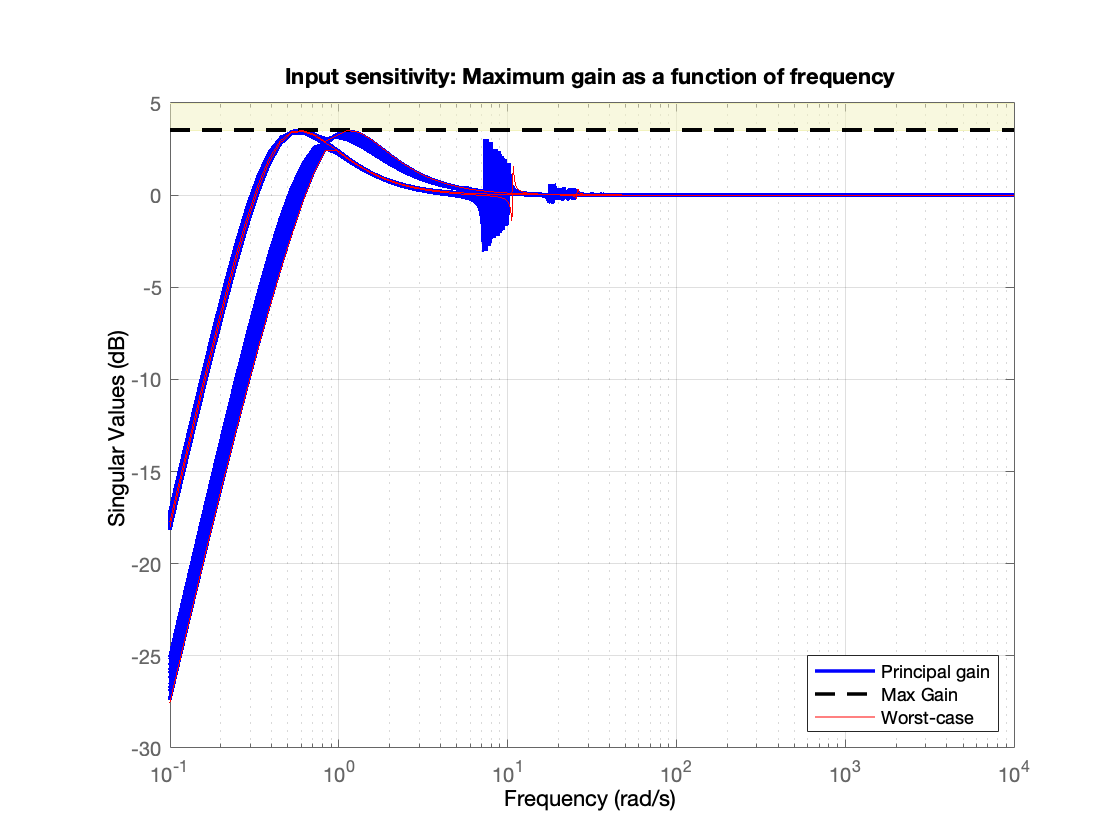

figure
viewGoal(Req2,PB2)
hold on
sigma(usubs(PB2,WCs(1)),'-r')  % worst performance:
legend('Principal gain','Max Gain','Worst-case','Location','southeast')

One can check that the worst-case identified by `systune` saturates the constraint in low frequency.

It is also possible to analyze the stability margins, axis per axis, on the Nichols frequency-domain responses of the open-loop transfer function (when the loop is opened on the system input):

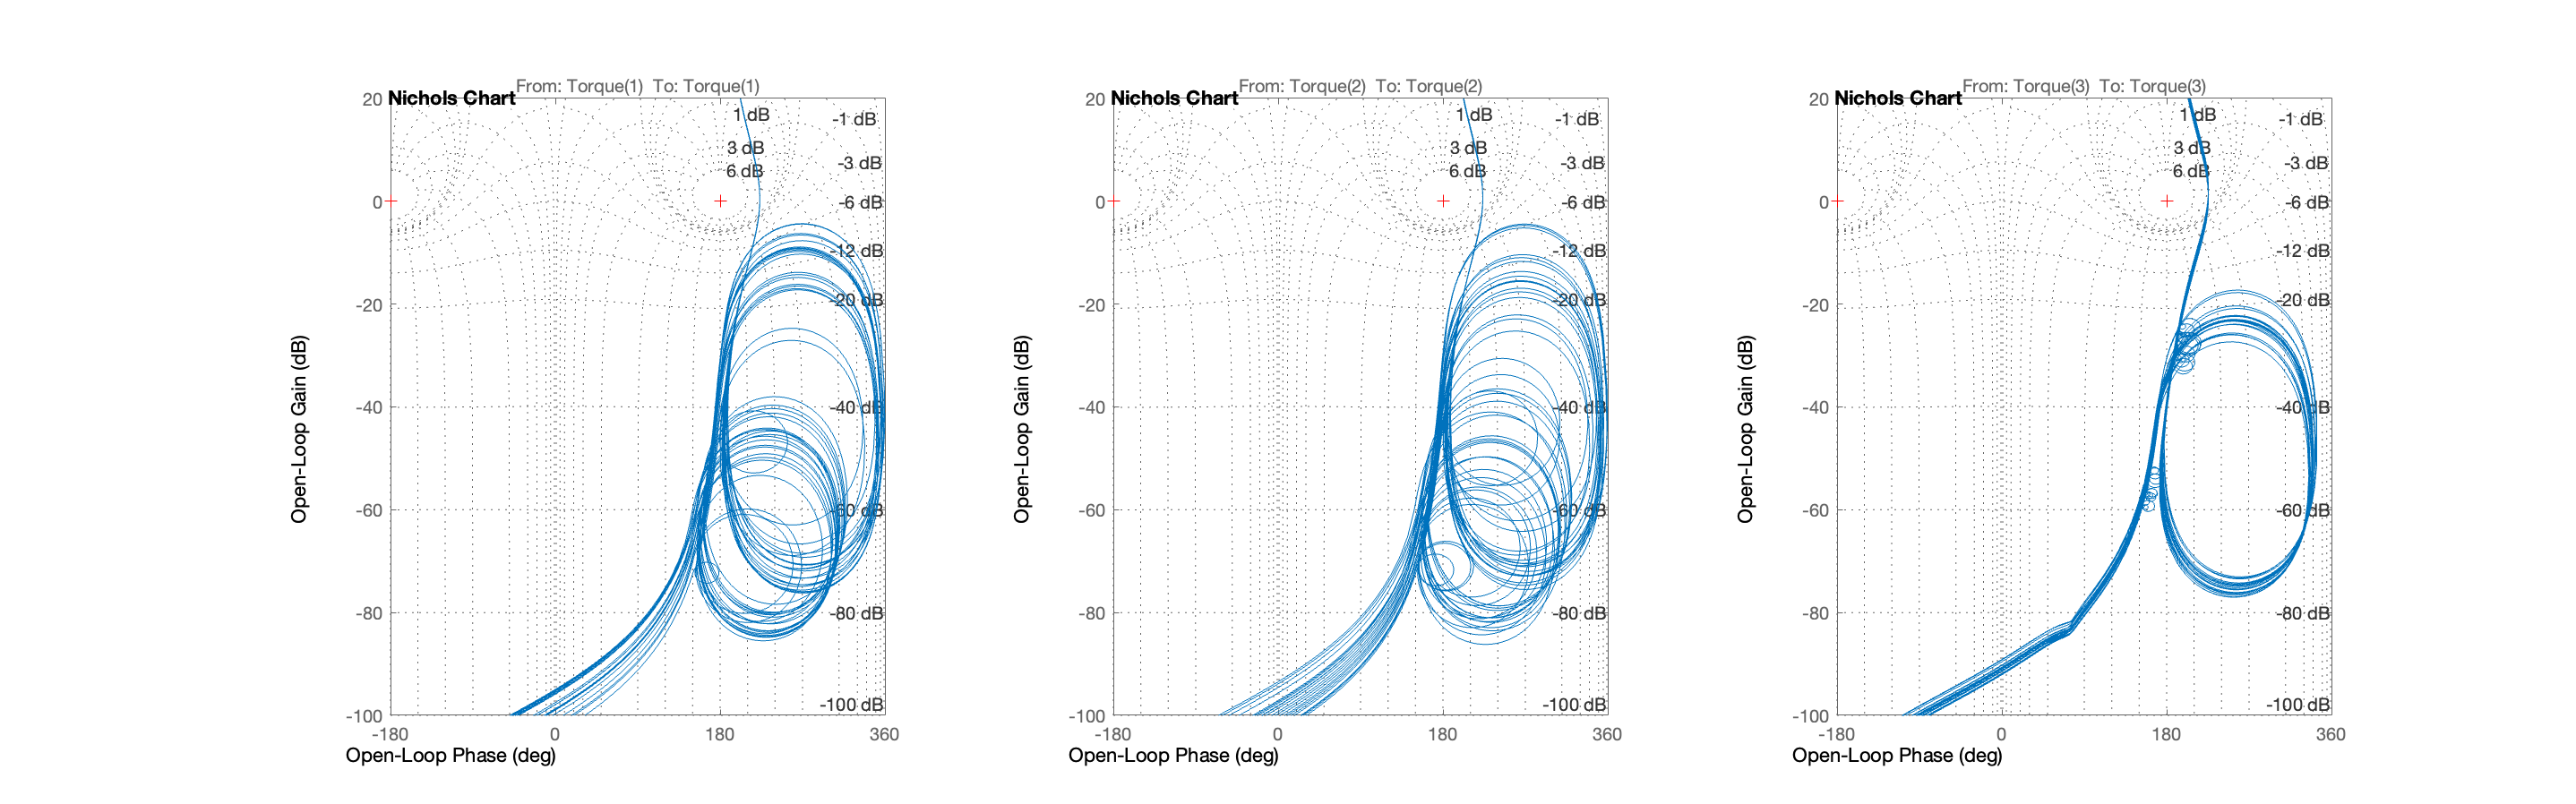

% Nichols plot of the open-loop transfer function:
% the loop is opened at the system input:
L = -getLoopTransfer(Popt,'Torque') ;
figure
for ii=1:3
    FDBCK=eye(3);
    FDBCK(ii,ii)=0;          % only the loop on channel # ii is opened!
    BFii=feedback(L,FDBCK);
    subplot(1,3,ii);
    nichols(BFii(ii,ii));
    ngrid
    set(gca,'Ylim',[-100 20]);
end
set(gcf,'Units','normalized','Position',[0 0 1 0.5])

One can check that the axis-per-axis stability margins (gain margins and phase margins) are largely better than the convervative lower bounds induced from `Req2` (gain margin $>\frac{\gamma}{\gamma-1}=3\;(9.54\;dB)$, phase margin $>2\arcsin\frac{1}{2\gamma}=38.9\,deg$) .

It is now possible to save the optimal closed-loop design `Popt` as an uncertain state space model **CLu**` (`**uss**`) `for simulation purpose. See also the tutorial 12: [***Simulating a SDTlib-based model***](matlab:open('../Tutorial12/tutorial12.html')) of the** full version** of the `SDTlib`***.***

% Save the optimal closed-loop system as an USS for simulation purpose:
% CLu=uss(getIOTransfer(Popt,{'Torb','Dsadm1','Dsadm2','Ngyro','Nsst'},...
%         {'Torque','ape'}));
% save OptimalDesign CLu